[https://www.dailymail.co.uk/sciencetech/article-11149371/Over-HALF-people-regularly-play-video-games-experience-gamer-rage.html](https://www.dailymail.co.uk/sciencetech/article-11149371/Over-HALF-people-regularly-play-video-games-experience-gamer-rage.html) (people who rage)

clear;

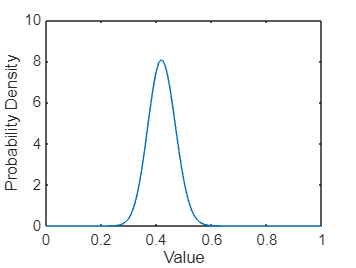

people = 100;
% Initialize distribution
a = 42; % First shape parameter
b = 58; % Second shape parameter
pd_beta = makedist('Beta', 'a', a, 'b', b);

% Visualize
x = linspace(0, 1, 200);
pr = pd_beta.pdf(x);
figure();
plot(x, pr)
xlabel('Value')
ylabel('Probability Density')

% title('Beta Distribution: a=8, b=8')

R = betarnd(42, 58, people, 1)

R =     0.3785
    0.4141
    0.4309
    0.4693
    0.4645
    0.3871
    0.3749
    0.4386
    0.5014
    0.3677


% gameSize = 10;
% baseAnger = .05;
% angerWithEnemy = .2;
% 
% % 10 separate graphs for 10 games 
% connections = group(gameSize, baseAnger, angerWithEnemy);
% 
% % There are 2 teams, so make a for loop that goes through it and strongly
% % connects the one person to the other team
% 
% connections
% 
% Angry = zeros(1,100);
% % randomly sample from 1,100)
% Angry(1) = 1
% AngerRate = transpose(R)


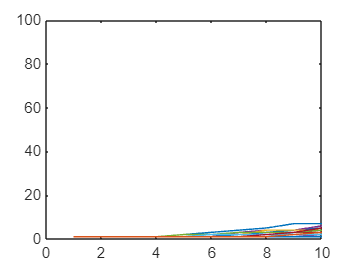

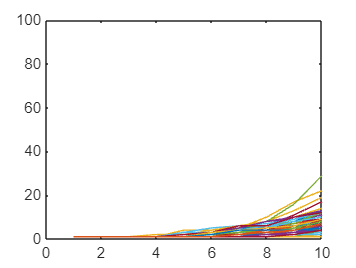

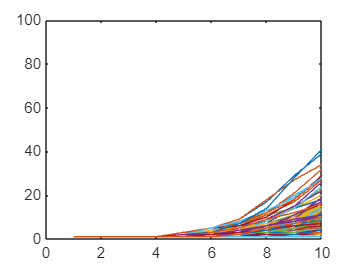

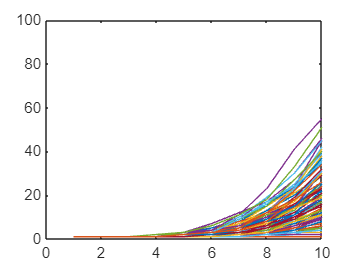

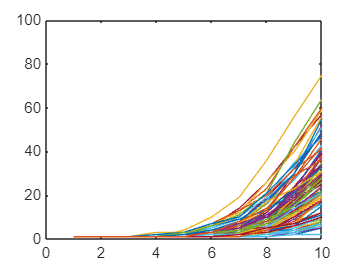

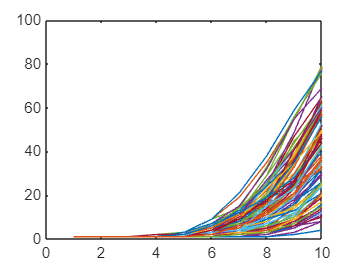

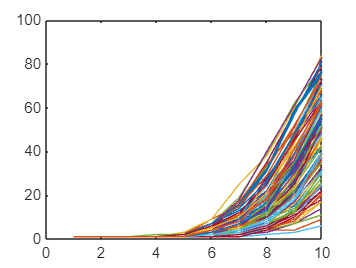

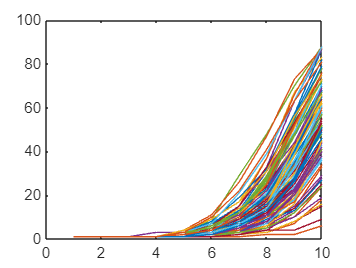

% %[Sh, Ih, Rh] = simulate_absir(M, Iv0, T recovery_rate)
% numTimeSteps = 10; 
% numGames = 10;
% n = 100;  % Total number of elements
% size = [10 10];  % Desired matrix dimensions
% R = transpose(R);
% R = reshape(R, 10, 10);
% IhOne = zeros(10);
% state = zeros(100,numTimeSteps+ 1);
% state(:,1) = Angry'
% totangry = zeros(100,1);
% figure;
TotEnd = zeros(10,1);
count = 1;
for k = 0:0.05:1
    hold off;
    Average = 0;
gameSize = 10;
baseAnger = .05;
angerWithEnemy = k;

% 10 separate graphs for 10 games 
connections = group(gameSize, baseAnger, angerWithEnemy);

% There are 2 teams, so make a for loop that goes through it and strongly
% connects the one person to the other team

connections;

Angry = zeros(1,100);
% randomly sample from 1,100)
Angry(1) = 1;
AngerRate = transpose(R);
%[Sh, Ih, Rh] = simulate_absir(M, Iv0, T recovery_rate)
numTimeSteps = 10; 
numGames = 10;
n = 100;  % Total number of elements
size = [10 10];  % Desired matrix dimensions
R = transpose(R);
R = reshape(R, 10, 10);
IhOne = zeros(10);
state = zeros(100,numTimeSteps+ 1);
state(:,1) = Angry';
totangry = zeros(100,1);
figure;

for j = 1:100
for i = 1: numTimeSteps
    % one time step
    y1 = betarnd(10*i, 100-10*i, 1, 1);
    shuffle = randperm(n);
    matrix = reshape(shuffle, size);
    % R(matrix(:,i)); NEEDS TO BE USED LATER
    for game = 1:numGames
        shuffled_angry = state(matrix(:,game),i);
        shuffled_r = R(:,1);
        % only Ih is important because we want to see how many people get
        % infected total
        % 2 because 1 is the base state, 2 is if one round went
        [sh, Ih, rh] = simulate_absir(connections, shuffled_angry, 2, 0, shuffled_r, y1); % recover rate is 0, they stay angry the whole time
        
        IhOne(:,game) = Ih(:,2);
        a = zeros(100,1);
        poop = shuffle';
        a(poop) = reshape(IhOne, 100,1);
        state(:,i+1) = a;
    end
end

totangry(j) = sum(state(:,11));
plot(sum(state))
hold on;
xlim([0 10]);
ylim([0 100]);

Average = Average + sum(state(:,11));
end

TotEnd(count) = Average/people;
count = count + 1;
end

function [connections] = group(numPeople, baseAnger, angerWithEnemy)
    connections = ones(numPeople,numPeople) - eye(numPeople);
    connections = connections * baseAnger;
    for i = 1: numPeople/2
        for j = numPeople/2 + 1: numPeople
            connections(i,j) = angerWithEnemy;
        end
    end
    for i = numPeople/2+1: numPeople
        for j = 1: numPeople/2
            connections(i,j) = angerWithEnemy;
        end
    end
end